# Derive the equations of motion of a Differential Drive Mobile Robot:

In this script we derive the equations of motion for a Differential Drive Robot (DDR).  The approach taken is to apply Newton's second law.   The modelling assumptions made, include:

- the vehicle can NOT slide in the direction of the BODY fixed Y-axis, ie: ${}^B_Gv^{\;}_{\textrm{Ay}}=0$.

- the wheels rotate without slipping. 

- the vehicle is a 2 degree of freedom (dof) system, characterised by the orentation angle $\theta$, and the velocity of the vehicle's centre of mass ${}^B_Gv^{\;}_{\textrm{Cx}}$ along the X-axis of the vehicle's body frame. 

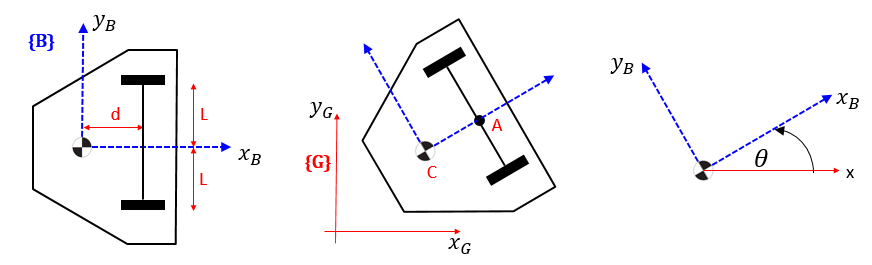     

Extensive use is made of the Symbolic toolbox throughout this derivation.  After deriving the vehicle's equations of motion, these equations are automatically converted into a MATLAB function block for Simulink.  This block can then be placed inside a Simulink model:

- `bh_DDR_component_model.slx`

`Bradley Horton : 01-Mar-2016, bradley.horton@mathworks.com.au`

## Equations of motion according to a body fixed frame:

Recall our fundamental equations of motion for a RIGID body - these equations are expressed in the body fixed {B}-frame:


$$^BF = m.(^B_Ga) = m.(\enspace ^B\dot{v}  \enspace + \enspace
{^B\omega} \times {^Bv} \enspace)$$



$$^BM = {^BI} . ^B\dot{\omega}  \enspace + \enspace
{^B\omega} \times ({^BI \thinspace. \thinspace ^B\omega}) \enspace$$


So let's explore our FORCE equation:

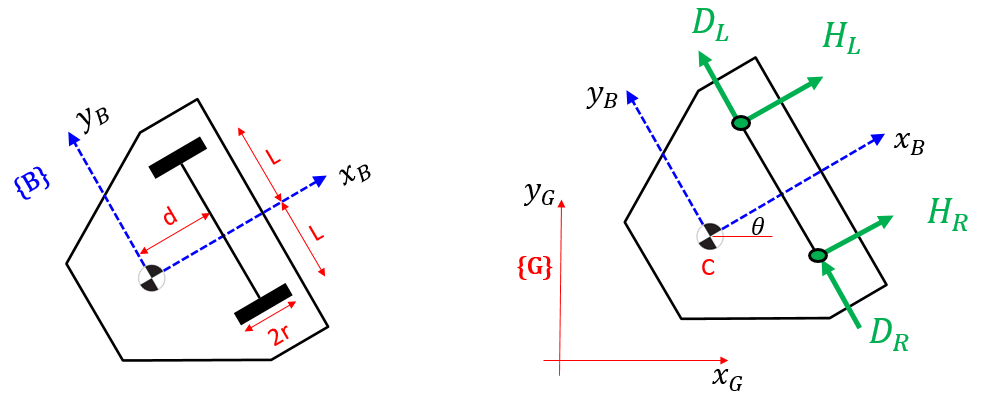

syms t theta(t) v_xB(t) v_yB(t) m

theta_dot = diff(theta(t), t);

w_B      = sym([0,0,theta_dot]).' ;
v_B      = [v_xB(t), v_yB(t), 0].';
v_B_dot  = diff(v_B, t);

So our FORCE equation becomes:

F_B = m*(v_B_dot + cross(w_B, v_B) )

$$F\_B = \left(\begin{array}{c} -m\,\left(v_{\mathrm{yB}}\left(t\right)\,\frac{\partial }{\partial t}\theta \left(t\right)-\frac{\partial }{\partial t}v_{\mathrm{xB}}\left(t\right)\right)\\ m\,\left(v_{\mathrm{xB}}\left(t\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+\frac{\partial }{\partial t}v_{\mathrm{yB}}\left(t\right)\right)\\ 0 \end{array}\right)$$

If we focus on the XY plane we see that the FORCE equations for our differential drive mobile robot is:                                    

-   $\left\lbrack \begin{array}{c}
{}^B_{\;}F^{\;}_X\\
{}^B_{\;}F^{\;}_Y
\end{array}\right\rbrack$ =$\;\;\;\left\lbrack \begin{array}{c}
H_R +H_L \\
D_R +D_L 
\end{array}\right\rbrack =m\ldotp \left\lbrack \begin{array}{c}
{}^B_Ga^{\;}_{\textrm{Cx}}\\
{}^B_Ga^{\;}_{\textrm{Cy}}
\end{array}\right\rbrack \;=\;m\ldotp \left\lbrack \begin{array}{c}
{}^B_G{\dot{v} }^{\;}_{\textrm{Cx}}\;-\dot{\;\theta } \ldotp {}^B_Gv^{\;}_{\textrm{Cy}}\\
{}^B_G{\dot{v} }^{\;}_{\textrm{Cy}}\;\;+\;\;\dot{\;\theta } \ldotp {}^B_Gv^{\;}_{\textrm{Cx}}
\end{array}\right\rbrack$    ............. ***(1.)***

Similarly let's consider our MOMENT equation:

syms I_xx I_xy I_xz I_yy I_yz I_zz

I       =  [ I_xx, I_xy, I_xz;
             I_xy, I_yy, I_yz;
             I_xz, I_yz, I_zz; ];
 
w_B_dot = [0,0, diff(theta(t),2)].' ;

M_B     = I*w_B_dot + cross(w_B, I*w_B)

$$M\_B = \left(\begin{array}{c} I_{\mathrm{xz}}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)-I_{\mathrm{yz}}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ I_{\mathrm{yz}}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+I_{\mathrm{xz}}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ I_{\mathrm{zz}}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right) \end{array}\right)$$

If we focus on the rotational motion about the Z-axis, we see that the TORQUE equation for our differential drive mobile robot is: 

-   $M_{\textrm{zB}} =\;\;d\ldotp \left(D_L +D_R \right)\;+\;\;\;L\ldotp \left(H_R -\;H_L \right)\;=\;I_{\textrm{zz}} \;\ldotp \;\theta^{\bullet \bullet }$   ............. ***(2.)*** 

## Focus on RIGHT wheel:

Consider the free body diagram of the RIGHT side wheel:

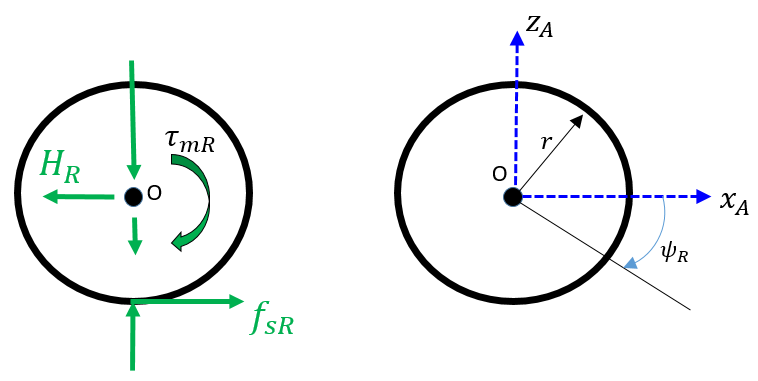 where:

- $r$     :  the wheel's radius

- $\psi_{R\;}$   :  the rotation angle of the wheel as measured from a body fixed frame at point A on the vehicle

- $f_{\textrm{sR}}$    :  the static friction acting on the wheel

- $H_R \;$   :  the reaction force applied from the vehicle body to the wheel shaft. An equal and opposite force will be applied from the wheel shaft back onto the vehicle 

- $\tau_{\textrm{mR}}$  :  the net torque applied to the wheel from an electric motor. $\tau_{\textrm{mR}} =K_a \ldotp i\;-b\ldotp {\psi^{\bullet } }_R =\;\tau_{\textrm{aR}} \;-\;b\ldotp {\psi^{\bullet } }_R$

- $\tau_{a\mathrm{R}}$   : the applied motor torque$\left(=\;K_a \ldotp i\right)$

- $K_{\mathrm{a}}$   :  the DC motor torque constant

- $i$      :  the DC motor curent

- $b_R$     :  the viscous damping co-efficient.

- $m_R$    :  the mass of the wheel

- $I_{\textrm{oR}}$    :  the combined inertia of the wheel and the motor shaft

We're also going to assume that there is NO slipping of the wheel, ie:

- ${\mathit{\mathbf{x}}}_{\mathit{\mathbf{o}}\;} =\mathit{\mathbf{r}}\ldotp \;\psi_{\mathit{\mathbf{R}}}$    ,    $\overset{\bullet }{{\mathit{\mathbf{x}}}_{\mathit{\mathbf{o}}\;} } =\mathit{\mathbf{r}}\ldotp \;\overset{\bullet }{\psi_{\mathit{\mathbf{R}}} }$     ,    $\overset{\bullet \bullet }{{\mathit{\mathbf{x}}}_{\mathit{\mathbf{o}}\;} } =\mathit{\mathbf{r}}\ldotp \;\overset{\bullet \bullet }{\psi_{\mathit{\mathbf{R}}} }$

So NEWTON's force law says:    

                                                  $m_R \;\overset{\bullet \bullet }{{\mathit{\mathbf{x}}}_{\mathit{\mathbf{o}}\;} }$ =  $\Sigma \;F=\;f_{\textrm{sR}} -\;H_R$

which we can write as:

                                           $m_R \;\ldotp \mathit{\mathbf{r}}\ldotp \;\overset{\bullet \bullet }{\psi_R }$  =$\;$$f_{\textrm{sR}} -\;H_R$     

and then isolating $f_{\textrm{sR}}$ we can write:

                                                $\;$$f_{\textrm{sR}}$  = $m_R \;\ldotp \mathit{\mathbf{r}}\ldotp \;\overset{\bullet \bullet }{\psi_{\mathit{\mathbf{R}}} } \;\;+\;\;H_R$     ............. ***(3.)*** 

Next, let's explore NEWTON's torque law:   

                                                $I_{\textrm{oR}} \;\ldotp \;\overset{\bullet \bullet }{\psi_R }$  = $\;\Sigma M=\;\tau_{\textrm{mR}} -\;r\ldotp \;f_{\textrm{sr}} \;$          

and then isolating $f_{\textrm{sR}}$ again we can write:

                                           $\;$$f_{\textrm{sR}}$  = $\left(\tau_{\textrm{mR}} \;-\;I_{\textrm{oR}} \;\ldotp \;\overset{\bullet \bullet }{\psi_R } \;\right)\frac{1}{r}$      ............. ***(4.)*** 

so now we can equate (3.) and (4.) and then isolate $H_{\mathrm{R}}$ :

                                        $\;$$f_{\textrm{sR}}$    =    $m_R \;\ldotp \mathit{\mathbf{r}}\ldotp \;\overset{\bullet \bullet }{\psi_R } \;\;+\;\;H_R \;\;\;=\;\;\left(\tau_{\textrm{mR}} \;-\;I_{\textrm{oR}} \;\ldotp \;\overset{\bullet \bullet }{\psi_R } \;\right)\frac{1}{r}$

and therefore we can express $H_{\mathrm{R}}$ as:

$\;$                                        $H_{\mathrm{R}}$    =    $\left(\tau_{\textrm{mR}} \;-\;I_{\textrm{oR}} \;\ldotp \;\overset{\bullet \bullet }{\psi_R } \;-\;m_R \;\ldotp r^2 \ldotp \;\overset{\bullet \bullet }{\psi_R } \right)\frac{1}{r}$

The last modification that we'll make to the $H_{\mathrm{R}}$ equation is to make the following substitution for $\tau_{\textrm{mR}}$ :

- $\tau_{\textrm{mR}} =K_a \ldotp i\;-b\ldotp {\psi^{\bullet } }_R =\;\tau_{\textrm{aR}} \;-\;b\ldotp {\psi^{\bullet } }_R$:

Which then makes our $H_R$ equation look like this:

- $\;$ $H_{\mathrm{R}}$    =    $\left(\tau_{\textrm{aR}} \;-\;b_R \ldotp {\psi^{\bullet } }_R \;-\;I_{\textrm{oR}} \;\ldotp \;\overset{\bullet \bullet }{\psi_R } \;-\;m_R \;\ldotp r^2 \ldotp \;\overset{\bullet \bullet }{\psi_R } \right)\frac{1}{r}$  .......... ***(5.)***  

- $\;$$f_{\textrm{sR}}$     = $\;\;\;m_R \;\ldotp \mathit{\mathbf{r}}\ldotp \;\overset{\bullet \bullet }{\psi_{\mathit{\mathbf{R}}} } \;\;+\;\;H_R$ 

Now if we applied an identical analysis to the LEFT wheel, we would get:

- $f_{\mathrm{s}L}$     = ${\;\;\;m}_L \;\ldotp \mathit{\mathbf{r}}\ldotp \;\overset{\bullet \bullet }{\psi_L } \;\;+\;\;H_L$     

-  $H_L$    =    $\left(\tau_{\mathrm{a}L} \;-\;b_L \ldotp {\psi^{\bullet } }_L \;-\;I_{\mathrm{o}L} \;\ldotp \;\overset{\bullet \bullet }{\psi_L } \;-\;m_L \;\ldotp r^2 \ldotp \;\overset{\bullet \bullet }{\psi_L } \right)\frac{1}{r}$  ............. ***(6.)*** 

# Explore velocities, accelerations and constraints:

Consider the following schematic:

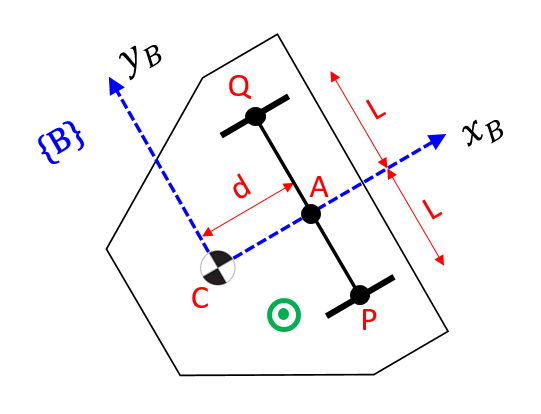

we're going to explore the velocities and accelerations of points A,Q and P.  Specifically we'll define:

${}^B_G{\omega }^{\;}_B=\;\left\lbrack \begin{array}{c}
0\\
0\\
\theta^{\bullet } 
\end{array}\right\rbrack$ ,  ${}^B_G{\alpha }^{\;}_B=\;\left\lbrack \begin{array}{c}
0\\
0\\
\theta^{\bullet \bullet } 
\end{array}\right\rbrack$ , ${}^B_Br^{\;}_{A|C}=\;\left\lbrack \begin{array}{c}
d\\
0\\
0
\end{array}\right\rbrack$ ,  ${}^B_Br^{\;}_{Q|C}=\;\left\lbrack \begin{array}{c}
d\\
L\\
0
\end{array}\right\rbrack$ , ${}^B_Br^{\;}_{P|C}=\;\left\lbrack \begin{array}{c}
d\\
-L\\
0
\end{array}\right\rbrack$

Also, we'll enforce a "NO lateral sliding" motion contraint on our model.  This constraint can be represented by enforcing a zero BODY Y axis velocity at point A on the vehicle ie:

- 
$${}^B_Gv^{\;}_{\textrm{Ay}}=0$$


Let's start with a clean slate:

clear

Define some symbols:

syms  a_Cx  a_Cy  a_Cz
syms  v_Cx  v_Cy  v_Cz
syms  d L theta_DOT  theta_DOT_DOT  

v_C   = [v_Cx,  v_Cy,  v_Cz].';
a_C   = [a_Cx,  a_Cy,  a_Cz].';
omega = [0, 0, theta_DOT].';
alpha = [0, 0, theta_DOT_DOT].';

r_A = [d, 0, 0].';
r_Q = [d, L, 0].';
r_P = [d,-L, 0].';

For a rigid body, we know that we can describe the velocity of any point "$\odot$" iff we know information about the velocity of point C along with the $\omega$ of the body.  And this relationship is described by the formula, where all vectors are expressed in components of the {B}-frame

-      ${}^B_Gv^{\;}_{\odot }=\;{}^B_Gv^{\;}_C\;\;+\;\;\left({}^B_G{\omega }^{\;}_B\;\times \;{}^B_Br^{\;}_{\odot |C}\right)\;$ 

**Velocity of point A:**

v_A = v_C + cross(omega, r_A)

$$v\_A = \left(\begin{array}{c} v_{\mathrm{Cx}}\\ v_{\mathrm{Cy}}+d\,\theta_{\mathrm{DOT}}\\ v_{\mathrm{Cz}} \end{array}\right)$$

**Velocity of point Q:**

v_Q = v_C + cross(omega, r_Q)

$$v\_Q = \left(\begin{array}{c} v_{\mathrm{Cx}}-L\,\theta_{\mathrm{DOT}}\\ v_{\mathrm{Cy}}+d\,\theta_{\mathrm{DOT}}\\ v_{\mathrm{Cz}} \end{array}\right)$$

**Velocity of point P:**

v_P = v_C + cross(omega, r_P)

$$v\_P = \left(\begin{array}{c} v_{\mathrm{Cx}}+L\,\theta_{\mathrm{DOT}}\\ v_{\mathrm{Cy}}+d\,\theta_{\mathrm{DOT}}\\ v_{\mathrm{Cz}} \end{array}\right)$$

Now ifff we wanted ${}^B_Gv^{\;}_{\textrm{Ay}}=0$, then we would need to have:

- 
$${}^B_Gv^{\;}_{C\mathrm{y}}=-d\ldotp \theta^{\bullet }$$
        

So let's apply this constraint to our velocities for A,Q,P:

v_A = subs(v_A, v_Cy, -d*theta_DOT);
v_Q = subs(v_Q, v_Cy, -d*theta_DOT);
v_P = subs(v_P, v_Cy, -d*theta_DOT);

So our velocities now look like this:

v_A

$$v\_A = \left(\begin{array}{c} v_{\mathrm{Cx}}\\ 0\\ v_{\mathrm{Cz}} \end{array}\right)$$

v_Q

$$v\_Q = \left(\begin{array}{c} v_{\mathrm{Cx}}-L\,\theta_{\mathrm{DOT}}\\ 0\\ v_{\mathrm{Cz}} \end{array}\right)$$

v_P

$$v\_P = \left(\begin{array}{c} v_{\mathrm{Cx}}+L\,\theta_{\mathrm{DOT}}\\ 0\\ v_{\mathrm{Cz}} \end{array}\right)$$

There is something else we can say about the velocities of points A,P,Q ... and that's their relationship with the wheel rotation velocities  ${\psi^{\bullet } }_L$ and ${\psi^{\bullet } }_R$ :

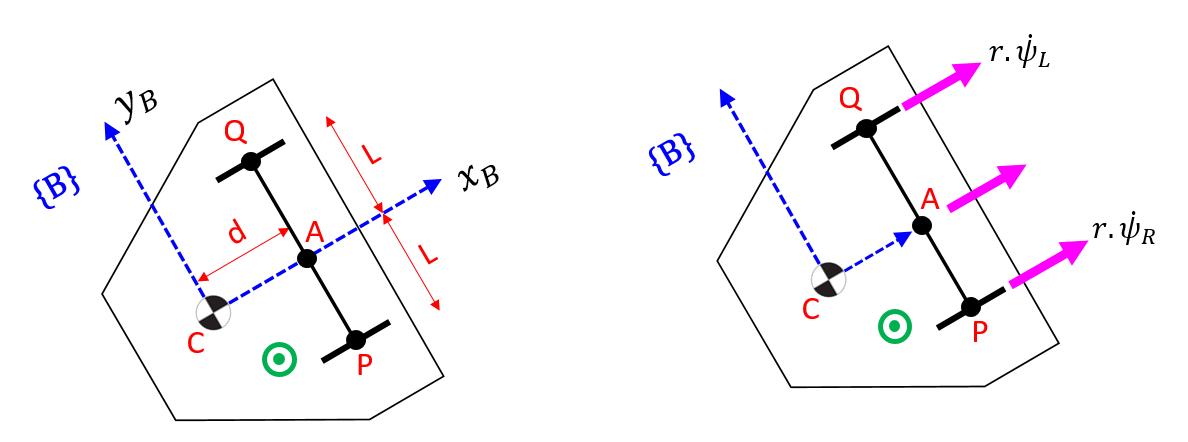

So what we have is:

syms r psi_L_DOT  psi_R_DOT
EQ_vQ = r*psi_L_DOT == v_Q(1);
EQ_vP = r*psi_R_DOT == v_P(1);

And we can solve this set of equations.  so solving for ${\theta^{\bullet } }$ and ${}^B_Gv^{\;}_{\textrm{Cx}}$:

v_sol_1 = solve([EQ_vQ, EQ_vP], [theta_DOT, v_Cx]);

so here's ${\theta^{\bullet } }$ :

the_theta_DOT = v_sol_1.theta_DOT

$$the\_theta\_DOT = -\frac{\psi_{L,\mathrm{DOT}}\,r-\psi_{R,\mathrm{DOT}}\,r}{2\,L}$$

so here's ${}^B_Gv^{\;}_{\textrm{Cx}}$:

the_v_Cx = v_sol_1.v_Cx

$$the\_v\_Cx = \frac{\psi_{L,\mathrm{DOT}}\,r}{2}+\frac{\psi_{R,\mathrm{DOT}}\,r}{2}$$

And similarly we could solve for ${\psi^{\bullet } }_R$ and ${\psi^{\bullet } }_L$ :

v_sol_2 = solve([EQ_vQ, EQ_vP], [psi_R_DOT, psi_L_DOT]);

so here's ${\psi^{\bullet } }_R$ :

the_psi_R_DOT = v_sol_2.psi_R_DOT

$$the\_psi\_R\_DOT = \frac{v_{\mathrm{Cx}}+L\,\theta_{\mathrm{DOT}}}{r}$$

so here's ${\psi^{\bullet } }_L$ :

the_psi_L_DOT = v_sol_2.psi_L_DOT

$$the\_psi\_L\_DOT = \frac{v_{\mathrm{Cx}}-L\,\theta_{\mathrm{DOT}}}{r}$$

Next let's explore **Accelerations**.  Again here is our system schematic: 

For a rigid body, we know that we can describe the acceleration of any point "$\odot$" iff we know information about the acceleration of point C along with the $\omega$ and $\alpha$ of the body.  And this relationship is described by the formula, where all vectors are expressed in components of the {B}-frame

-     
$${}^B_Ga^{\;}_{\odot }=\;{}^B_Ga^{\;}_C\;\;+\;\;\left({}^B_G{\alpha }^{\;}_B\;\times \;{}^B_Br^{\;}_{\odot |C}\right)\;\;+\;\;\;{}^B_G{\omega }^{\;}_B\;\times \left({}^B_G{\omega }^{\;}_B\;\times \;\;{}^B_Br^{\;}_{\odot |C}\right)$$
 

**Acceleration of point A:**

a_A = a_C + cross(alpha, r_A)  +  cross(omega, cross(omega, r_A) )

$$a\_A = \left(\begin{array}{c} a_{\mathrm{Cx}}-d\,{\theta_{\mathrm{DOT}}}^{2}\\ a_{\mathrm{Cy}}+d\,\theta_{\mathrm{DOT},\mathrm{DOT}}\\ a_{\mathrm{Cz}} \end{array}\right)$$

**Acceleration of point Q:**

a_Q = a_C + cross(alpha, r_Q)  +  cross(omega, cross(omega, r_Q) )

$$a\_Q = \left(\begin{array}{c} -d\,{\theta_{\mathrm{DOT}}}^{2}+a_{\mathrm{Cx}}-L\,\theta_{\mathrm{DOT},\mathrm{DOT}}\\ -L\,{\theta_{\mathrm{DOT}}}^{2}+a_{\mathrm{Cy}}+d\,\theta_{\mathrm{DOT},\mathrm{DOT}}\\ a_{\mathrm{Cz}} \end{array}\right)$$

**Acceleration of point P:**

a_P = a_C + cross(alpha, r_P)  +  cross(omega, cross(omega, r_P) )

$$a\_P = \left(\begin{array}{c} -d\,{\theta_{\mathrm{DOT}}}^{2}+a_{\mathrm{Cx}}+L\,\theta_{\mathrm{DOT},\mathrm{DOT}}\\ L\,{\theta_{\mathrm{DOT}}}^{2}+a_{\mathrm{Cy}}+d\,\theta_{\mathrm{DOT},\mathrm{DOT}}\\ a_{\mathrm{Cz}} \end{array}\right)$$

We can insert into these acceleration expressions what we now know about ${}^B_Gv^{\;}_{C\mathrm{y}}$ and ${}^B_Ga^{\;}_{\textrm{Cx}}$ :

- 
$${}^B_Ga^{\;}_{\textrm{Cx}}=\;{}^B_G{\dot{v} }^{\;}_{\textrm{Cx}}\;-\dot{\;\theta } \ldotp {}^B_Gv^{\;}_{\textrm{Cy}}$$


- 
$${}^B_Gv^{\;}_{C\mathrm{y}}=-d\ldotp \;\theta^{\bullet }$$


syms v_Cx_DOT
a_A = subs(a_A, a_Cx, (v_Cx_DOT -theta_DOT*(-d*theta_DOT)) )

$$a\_A = \left(\begin{array}{c} v_{\mathrm{Cx},\mathrm{DOT}}\\ a_{\mathrm{Cy}}+d\,\theta_{\mathrm{DOT},\mathrm{DOT}}\\ a_{\mathrm{Cz}} \end{array}\right)$$

a_Q = subs(a_Q, a_Cx, (v_Cx_DOT -theta_DOT*(-d*theta_DOT)) )

$$a\_Q = \left(\begin{array}{c} v_{\mathrm{Cx},\mathrm{DOT}}-L\,\theta_{\mathrm{DOT},\mathrm{DOT}}\\ -L\,{\theta_{\mathrm{DOT}}}^{2}+a_{\mathrm{Cy}}+d\,\theta_{\mathrm{DOT},\mathrm{DOT}}\\ a_{\mathrm{Cz}} \end{array}\right)$$

a_P = subs(a_P, a_Cx, (v_Cx_DOT -theta_DOT*(-d*theta_DOT)) )

$$a\_P = \left(\begin{array}{c} v_{\mathrm{Cx},\mathrm{DOT}}+L\,\theta_{\mathrm{DOT},\mathrm{DOT}}\\ L\,{\theta_{\mathrm{DOT}}}^{2}+a_{\mathrm{Cy}}+d\,\theta_{\mathrm{DOT},\mathrm{DOT}}\\ a_{\mathrm{Cz}} \end{array}\right)$$

There is something else we can say about the accelerations of points A,P,Q ... and that's their relationship with the wheel rotation accelerations   ${\psi^{\bullet \bullet } }_L$ and ${\psi^{\bullet \bullet } }_R$ :

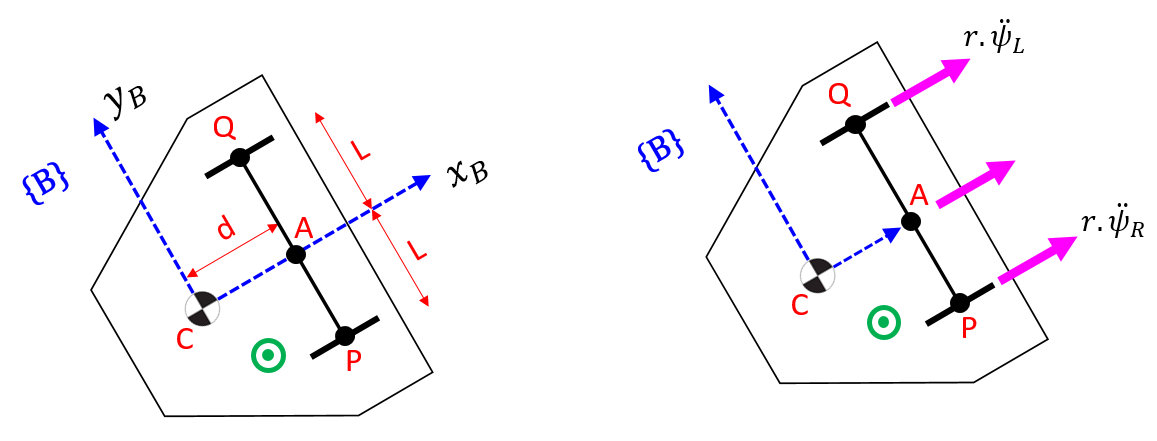

So what we have is:

syms r psi_L_DOT_DOT  psi_R_DOT_DOT

EQ_aQ = r*psi_L_DOT_DOT == a_Q(1);
EQ_aP = r*psi_R_DOT_DOT == a_P(1);

And we can solve this set of equations.  Solving for ${\psi^{\bullet \bullet } }_R$ and ${\psi^{\bullet \bullet } }_L$ :

a_sol_2 = solve([EQ_aQ, EQ_aP], [psi_R_DOT_DOT, psi_L_DOT_DOT]);

so here's ${\psi^{\bullet \bullet } }_L$ :

the_psi_L_DOT_DOT = a_sol_2.psi_L_DOT_DOT

$$the\_psi\_L\_DOT\_DOT = \frac{v_{\mathrm{Cx},\mathrm{DOT}}-L\,\theta_{\mathrm{DOT},\mathrm{DOT}}}{r}$$

so here's ${\psi^{\bullet \bullet } }_R$ :

the_psi_R_DOT_DOT = a_sol_2.psi_R_DOT_DOT

$$the\_psi\_R\_DOT\_DOT = \frac{v_{\mathrm{Cx},\mathrm{DOT}}+L\,\theta_{\mathrm{DOT},\mathrm{DOT}}}{r}$$

# Continue with the EOMs:

Now that we've defined some key relationships, we can revisit our equations of motion.  First let's clear away some of our workspace variables ... and keep some:

clearvars -except L r d a_sol_2 v_sol_2 a_Cx v_Cx theta_DOT theta_DOT_DOT

Define some new SYMS:

syms theta v_Cx v_Cx_DOT  
syms theta  TaL TaR bR bL
syms I_zz  I_wR  I_wL  m m_wR  m_wL

Recall the Newtons equations that we derived earlier:

-   $\left\lbrack \begin{array}{c}
{}^B_{\;}F^{\;}_X\\
{}^B_{\;}F^{\;}_Y
\end{array}\right\rbrack$ =$\;\;\;\left\lbrack \begin{array}{c}
H_R +H_L \\
D_R +D_L 
\end{array}\right\rbrack =m\ldotp \left\lbrack \begin{array}{c}
{}^B_Ga^{\;}_{\textrm{Cx}}\\
{}^B_Ga^{\;}_{\textrm{Cy}}
\end{array}\right\rbrack \;=\;m\ldotp \left\lbrack \begin{array}{c}
{}^B_G{\dot{v} }^{\;}_{\textrm{Cx}}\;-\theta^˙ \ldotp {}^B_Gv^{\;}_{\textrm{Cy}}\\
{}^B_G{\dot{v} }^{\;}_{\textrm{Cy}}\;\;+\;\;\dot{\;\theta } \ldotp {}^B_Gv^{\;}_{\textrm{Cx}}
\end{array}\right\rbrack$  

-   ${\;\;\;\;M}_{\textrm{zB}}$  = $\;d\ldotp \left(D_L +D_R \right)\;+\;\;\;L\ldotp \left(H_R -\;H_L \right)\;$= $\;I_{\textrm{zz}} \;\ldotp \;\theta^{\bullet \bullet }$   

So now we can combine some of the key results and substitute them into our original equations of motion analysis.  The key relations that we derived were:

- ${}^B_Gv^{\;}_{C\mathrm{y}}=-d\ldotp \;\theta^{\bullet }$    and    ${}^B_G{\dot{v} }^{\;}_{\textrm{Cy}}$ = $-d\ldotp \;\theta^{\bullet \bullet }$

my_v_Cy      = -d*theta_DOT;
my_v_Cy_DOT  = -d*theta_DOT_DOT;

- 
$$\left\lbrack \begin{array}{c}
{}^B_Ga^{\;}_{\textrm{Cx}}\\
{}^B_Ga^{\;}_{\textrm{Cy}}
\end{array}\right\rbrack \;=\left\lbrack \begin{array}{c}
{}^B_G{\dot{v} }^{\;}_{\textrm{Cx}}\;-\dot{\;\theta } \ldotp {}^B_Gv^{\;}_{\textrm{Cy}}\\
{}^B_G{\dot{v} }^{\;}_{\textrm{Cy}}\;\;+\;\;\dot{\;\theta } \ldotp {}^B_Gv^{\;}_{\textrm{Cx}}
\end{array}\right\rbrack$$


my_a_Cx      =    v_Cx_DOT - theta_DOT*my_v_Cy;
my_a_Cy      = my_v_Cy_DOT + theta_DOT*v_Cx;

- ${\psi^{\bullet } }_R$ = $\left({}^B_Gv^{\;}_{\textrm{Cx}}+L\ldotp \theta^{\bullet } \right)\frac{1}{r}$    and   ${\psi^{\bullet } }_L$ = $\left({}^B_Gv^{\;}_{\textrm{Cx}}-L\ldotp \theta^{\bullet } \right)\frac{1}{r}$

my_psi_R_DOT  = v_sol_2.psi_R_DOT;
my_psi_L_DOT  = v_sol_2.psi_L_DOT;

- 
$${\psi^{\bullet \bullet } }_R =\;\left(-d\ldotp \overset{\bullet }{\theta^2 } \;\;+\;\;{}^B_Ga^{\;}_{\textrm{Cx}}\;\;+\;L\ldotp \theta^{\bullet \bullet } \right)\frac{1}{r}$$


- 
$${\psi^{\bullet \bullet } }_L =-\left(d\ldotp \overset{\bullet }{\theta^2 } \;-\;\;{}^B_Ga^{\;}_{\textrm{Cx}}\;\;+\;L\ldotp \theta^{\bullet \bullet } \right)\frac{1}{r}$$


my_psi_R_DOT_DOT = a_sol_2.psi_R_DOT_DOT;
my_psi_L_DOT_DOT = a_sol_2.psi_L_DOT_DOT;

- 
$$H_R \;\;\;=\;\left(\tau_{\textrm{aR}} \;-\;b_R \ldotp {\psi^{\bullet } }_R \;-\;I_{\textrm{oR}} \;\ldotp \;\overset{\bullet \bullet }{\psi_R } \;-\;m_R \;\ldotp r^2 \ldotp \;\overset{\bullet \bullet }{\psi_R } \right)\frac{1}{r}$$


- 
$$H_L \;\;\;=\;\left(\tau_{\mathrm{a}L} \;-\;b_L \ldotp {\psi^{\bullet } }_L \;\;-\;I_{\mathrm{o}L} \;\ldotp \;\overset{\bullet \bullet }{\psi_L } \;\;-\;m_L \;\ldotp r^2 \ldotp \;\overset{\bullet \bullet }{\psi_L } \right)\frac{1}{r}$$


HR = (TaR -bR*my_psi_R_DOT - I_wR*my_psi_R_DOT_DOT - m_wR*(r^2)*my_psi_R_DOT_DOT)/r;
HL = (TaL -bL*my_psi_L_DOT - I_wL*my_psi_L_DOT_DOT - m_wL*(r^2)*my_psi_L_DOT_DOT)/r;
%NOTE: the resulting solutions for v_Cx_DOT, theta_DOT_DOT are greatly simplified
%      when you make the masses and inertias of the 2 wheels the same. 
%HL = (TaL -bL*my_psi_L_DOT - I_wR*my_psi_L_DOT_DOT - m_wR*(r^2)*my_psi_L_DOT_DOT)/r;

So let's define one equation - and it will be the ${}^B_{\;}F^{\;}_X$ equation:

- $\left\lbrack \begin{array}{c}
{}^B_{\;}F^{\;}_X\\
{}^B_{\;}F^{\;}_Y
\end{array}\right\rbrack$ =$\;\;\;\left\lbrack \begin{array}{c}
H_R +H_L \\
D_R +D_L 
\end{array}\right\rbrack =m\ldotp \left\lbrack \begin{array}{c}
{}^B_Ga^{\;}_{\textrm{Cx}}\\
{}^B_Ga^{\;}_{\textrm{Cy}}
\end{array}\right\rbrack \;=\;m\ldotp \left\lbrack \begin{array}{c}
{}^B_G{\dot{v} }^{\;}_{\textrm{Cx}}\;-\dot{\;\theta } \ldotp {}^B_Gv^{\;}_{\textrm{Cy}}\\
{}^B_G{\dot{v} }^{\;}_{\textrm{Cy}}\;\;+\;\;\dot{\;\theta } \ldotp {}^B_Gv^{\;}_{\textrm{Cx}}
\end{array}\right\rbrack$  

EQ_F = (HR + HL) == (m * my_a_Cx);

For the 2nd equation, we'll focus on our moment equation ... where we'll substiture the $\left(D_L +D_R \right)$term with our ($m\ldotp {}^B_Ga^{\;}_{\textrm{Cy}}$) relationship :

-   ${\;\;\;\;M}_{\textrm{zB}}$  = $\;d\ldotp \left(D_L +D_R \right)\;+\;\;\;L\ldotp \left(H_R -\;H_L \right)\;$= $\;I_{\textrm{zz}} \;\ldotp \;\theta^{\bullet \bullet }$     

DR_plus_DL = m*my_a_Cy;
EQ_M       = (d*DR_plus_DL + L*(HR-HL)) == (I_zz*theta_DOT_DOT);

So can we solve for $\theta^{\bullet \bullet }$ and ${}^B_G{\dot{v} }^{\;}_{\textrm{Cx}}$:

S = solve([EQ_F, EQ_M], [v_Cx_DOT, theta_DOT_DOT])

S = struct with fields:
         v_Cx_DOT: [1×1 sym]
    theta_DOT_DOT: [1×1 sym]